folder = "11_04_22/catapult_data/*.csv";
files = dir(folder);
display(files)

files = 9×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


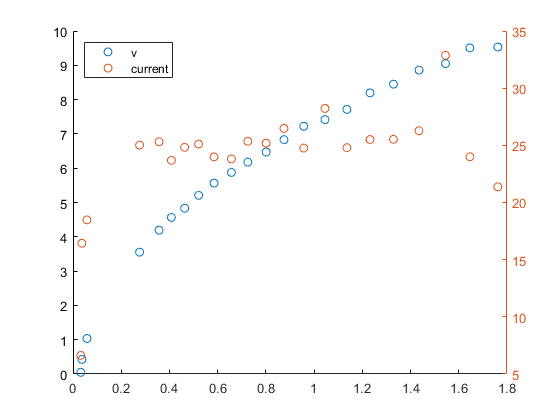

file_num = 7; %start at 3
file = importdata(files(file_num).folder + "/" + files(file_num).name, ",");
catapult_data = file.data(file.data(:,1) < 2000000, :);
clf
hold on
scatter(catapult_data(:,1), catapult_data(:,2))
yyaxis right
scatter(catapult_data(:,1), -catapult_data(:,3))
%scatter(data(:,1), data(:,4))
legend(["v", "current"], 'Location','northwest' )
hold off

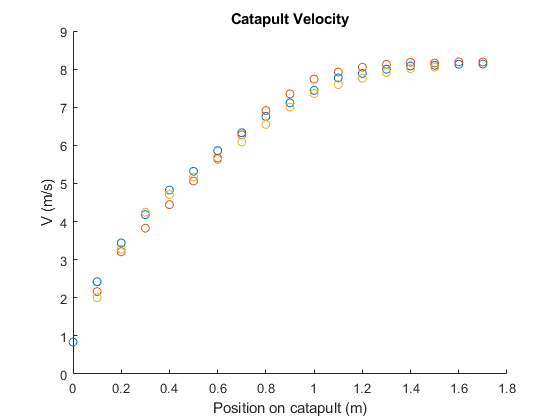

clf
hold on
catapult_new_time = 0:0.1:2;
for num = [1,8,9]
    file = importdata(files(num).folder + "/" + files(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.84, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_time);
    scatter(catapult_new_time, new)
end
hold off
ylabel("V (m/s)")
xlabel("Position on catapult (m)")
title("Catapult Velocity")

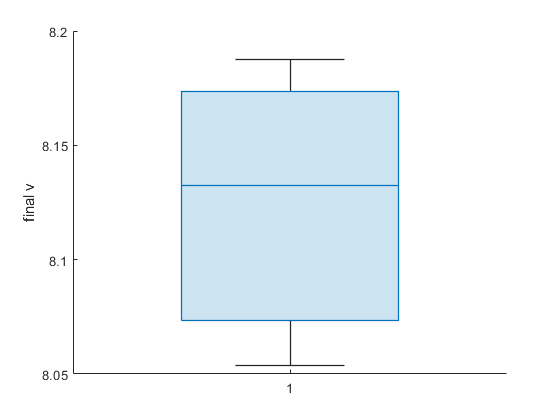

final_v = [];
clf
hold on
catapult_new_time = 0:0.1:2;
for num = [1,8,9]
    file = importdata(files(num).folder + "/" + files(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.8, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_time);
    new = new(~isnan(new));
    new = new(new>1.75);
    final_v = [final_v new(end)];
end
boxchart(final_v);
hold off
ylabel("final v")

std(final_v)

ans = 0.0673